# Funciones matemáticas

MATLAB dispone de diversas funciones de distintas áreas de la matemática y todas estas funciones se encuentran vectorizadas, es decir, funcionan con escalares, vectores y matrices sin ningún problema.

## Trigonometría

Las funciones trigonométricas de MATLAB calculan valores trigonométricos estándar en radianes o grados, valores trigonométricos hiperbólicos en radianes y variantes inversas de cada función.

Para empezar hablaremos acerca de las funciones de conversión de grados a radianes.

### Funciones `rad2deg` y `deg2rad`

Es posible utilizar las funciones `rad2deg` (radianes a grados) y `deg2rad` (grados a radianes) para convertir entre radianes y grados, o viceversa.

clear

% Crear un vector de radianes y grados.
anguloRad = linspace(0, pi, 7);
anguloGrad = 0:30:180;

% Conversión de radianes a grados.
rad2deg(anguloRad)

ans =          0   30.0000   60.0000   90.0000  120.0000  150.0000  180.0000


% Conversión de radianes a grados.
deg2rad(anguloGrad)

ans =          0    0.5236    1.0472    1.5708    2.0944    2.6180    3.1416


### Funciones `cart2pol` y `pol2cart`

Las funciones `cart2pol` (cartesiano a polar) y `pol2cart` (polar a cartesiano) permiten convertir vectores entre sistemas de coordenadas.

clear

% Crear vectores x, y.
x = [3 3 3];
y = [1 2 3];

% Conversión de coordenadas cartesianas a polares.
[th, rh] = cart2pol(x, y)

th =     0.3218    0.5880    0.7854


rh =     3.1623    3.6056    4.2426


% Crear vectores theta y rho.
theta = deg2rad([30 45 60]);
rho = [2 3 4];

% Conversión de coordenadas polares a cartesianas.
[x, y] = pol2cart(theta, rho);
x

x =     1.7321    2.1213    2.0000


y

y =     1.0000    2.1213    3.4641


### Función `hypot`

La función `hypot` permite obtener la raíz cuadrada de la suma de los cuadrados de dos números, es decir, la hipotenusa.


$$h=\sqrt{a^2 +b^2 }$$


clear

% Crear un punto x, y.
x = 1:5;
y = 10:-2:2;

% Obtener la hipotenusa.
hypot(x, y)

ans =    10.0499    8.2462    6.7082    5.6569    5.3852


### Funciones seno

MATLAB dispone de la función seno, su inversa, su hiperbólica y algunas variantes más.

**Figura 1.** Funciones seno dentro de MATLAB.

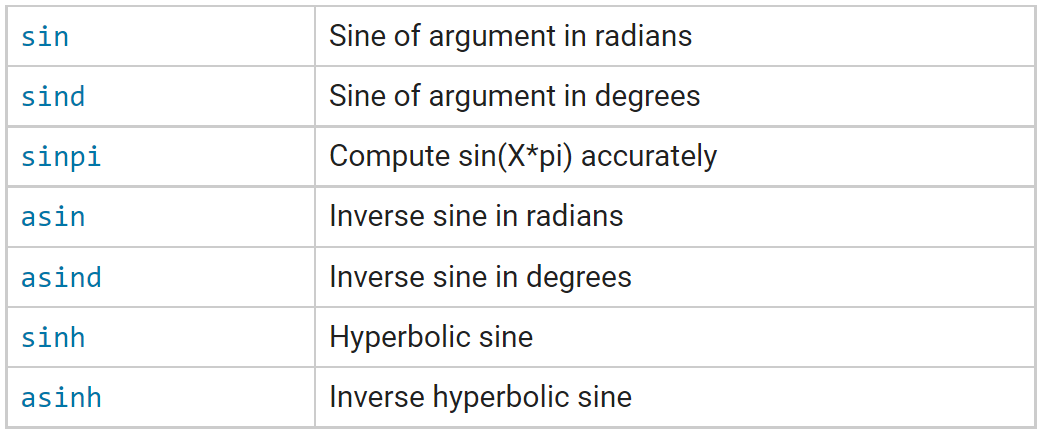

*Tomado de *[*MathWorks: Trigonometry*](https://www.mathworks.com/help/matlab/trigonometry.html)*.*

Veamos algunos ejemplos utilizando algunas de estas funciones.

clear

% Función: sin
angRad = 0:pi/2:2*pi;
sin(angRad)

ans =          0    1.0000    0.0000   -1.0000   -0.0000


% Función: sind
angDeg = 0:90:360;
sind(angDeg)

ans =      0     1     0    -1     0


% Función: sinpi
n = 0:0.5:2;
sinpi(n)

ans =      0     1     0    -1     0


### Funciones coseno

MATLAB dispone de la función coseno, su inversa, su hiperbólica y algunas variantes más.

**Figura 2.** Funciones coseno dentro de MATLAB.

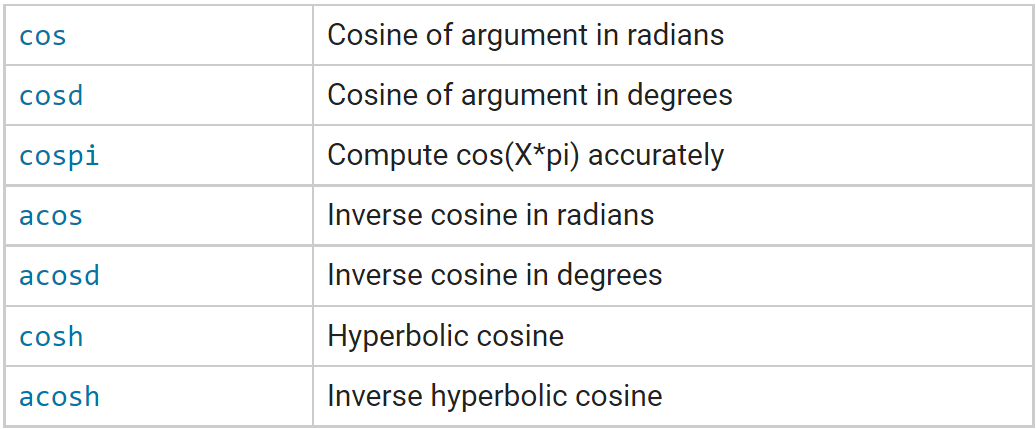

*Tomado de *[*MathWorks: Trigonometry*](https://www.mathworks.com/help/matlab/trigonometry.html)*.*

Veamos algunos ejemplos utilizando algunas de estas funciones.

clear

% Función: cos
angRad = 0:pi/2:2*pi;
cos(angRad)

ans =     1.0000    0.0000   -1.0000   -0.0000    1.0000


% Función: sind
angDeg = 0:90:360;
cosd(angDeg)

ans =      1     0    -1     0     1


% Función: sinpi
n = 0:0.5:2;
cospi(n)

ans =      1     0    -1     0     1


### Funciones tangente

MATLAB dispone de la función coseno, su inversa, su hiperbólica y algunas variantes más.

**Figura 3.** Funciones tangente dentro de MATLAB.

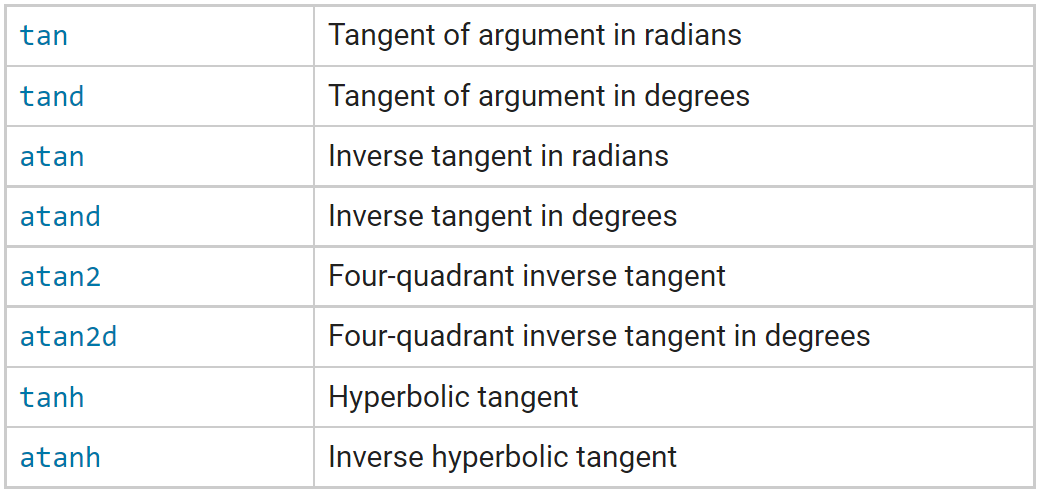

*Tomado de *[*MathWorks: Trigonometry*](https://www.mathworks.com/help/matlab/trigonometry.html)*.*

Veamos algunos ejemplos utilizando algunas de estas funciones.

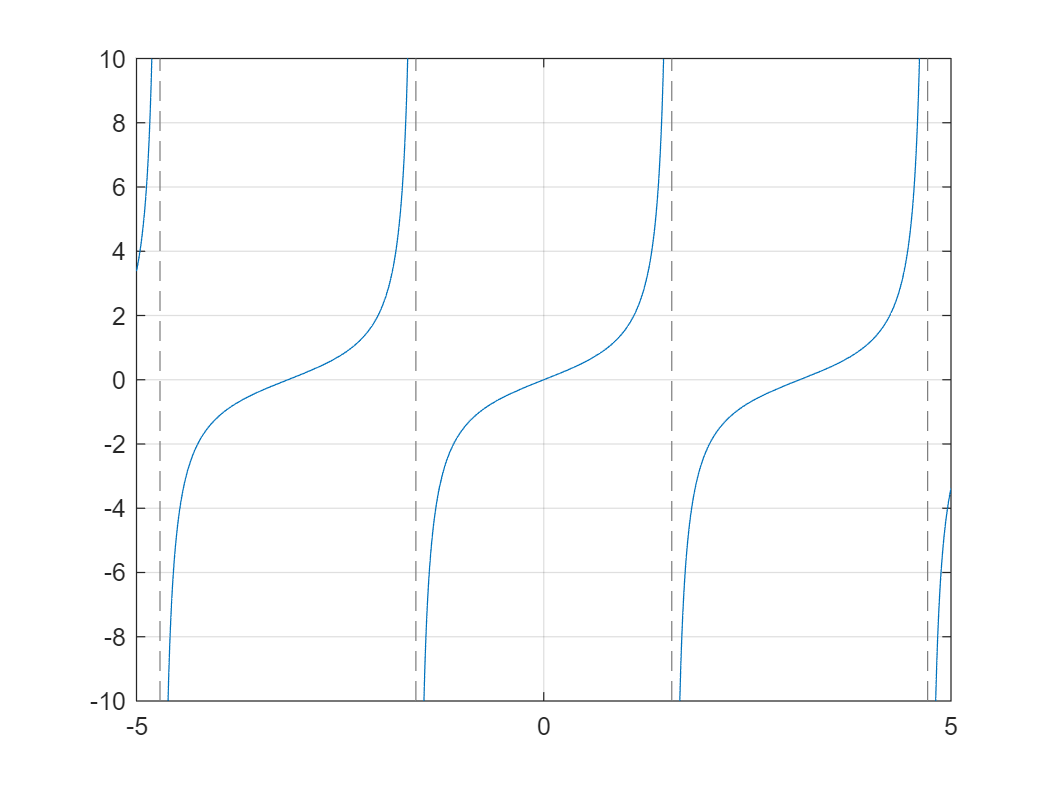

clear

% Ignorar las siguientes dos líneas de código. Se explicarán más adelante.
fplot(@tan)
grid on

% Función: tan
angRad = -pi/2:pi/4:pi/2;
tan(angRad)

ans = 1.0e+16 *

   -1.6331   -0.0000         0    0.0000    1.6331


% Función: tand
angDeg = -90:45:90;
tand(angDeg)

ans =   -Inf    -1     0     1   Inf


### Más funciones trigonométricas

Este curso no está enfocado en el estudio de las funciones trigonométricas, por lo que se detallaron previamente las más funciones más usuales. No obstante, si se desea profundizar el en el estudio de la trigonometría utilizando MATLAB, en el materia adicional se adjuntó un enlace a la documentación de MATLAB acerca de la trigonometría.

## Exponentes y logaritmos

### Función `exp`

La función exponencial `exp` tiene como base el número de Euler $e$ y como pontencia el argumento que se le ingrese.

Debemos recordar que la función exponencial es $e^x$, es por eso que el número de Euler dentro de MATLAB se lo obtiene con esta función: `exp(1)`, lo cual vendría a significar $e^1$, pero esta expresión claramente es $e$.

clear

% Número de Euler
exp(1)

ans = 2.7183

### Funciones `log` y `log10`

La función `log` permite determinar el logaritmo natural, o logaritmo neperiano, de un número.

No se debe confundir con la notación matemática $\ln \left(x\right)$, puesto que la función interna `ln` no existe.

clear

% Determinar el logaritmo natural del número de Euler.
EulerNumber = exp(1);
log(EulerNumber)

ans = 1

Por otra parte, la función `log10` permite determinar el logaritmo en base 10 de un número.

% Determinar el logaritmo base 10 de varios números que son potencias de
% 10.
n = logspace(0, 3, 4)

n =            1          10         100        1000


log10(n)

ans =      0     1     2     3


#### Observación

No existe una función que permita realizar el logaritmo de un número en una base en específico que no sean el número de Euler y el número 10. No obstante, es bastante sencillo construirla a partir de una función local o una función anónima, pero esto se lo discutirá más adelante.

### Funciones `sqrt` y `nthroot`

La función `sqrt` permite determinar la raíz cuadrada de un número. Si el número es negativo devolverá un número complejo.

clear

% Función sqrt con números positivo.
n = [1 4 9 16 25];
sqrt(n)

ans =      1     2     3     4     5


% Función sqrt con números positivo y negativos.
n = [1 4 -9 16 25];
sqrt(n)

ans =    1.0000 + 0.0000i   2.0000 + 0.0000i   0.0000 + 3.0000i   4.0000 + 0.0000i   5.0000 + 0.0000i


La función `nthroot` permite determinar la raíz *n-ésima* de un número.

% Números para deteminar la raíz con n = 3.
n = [1 8 27 64];
nthroot(n, 3)

ans =      1     2     3     4


## Matemática discreta

Las funciones matemáticas discretas realizan operaciones con números enteros $\left(\ldotp \ldotp \ldotp ,-2,-1,0,1,2,\ldotp \ldotp \ldotp \right)$ o devuelven una salida discreta como números enteros. Es posible utilizar estas funciones para factorizar números grandes, calcular factoriales, encontrar el máximo común denominador (m.c.m), etc.

### Función `factor` 

La función `factor` devuelve un vector en donde se encontrarán los factores primos del número.

clear

n = 133;
factor(n)

ans =      7    19


### Funciones `primes` y `factorial`

La función `primes` permite determiar todos los números primos menores o iguales al número ingresado. Estos números los devuelven en un vector.

clear

n = 25;
primes(n)

ans =      2     3     5     7    11    13    17    19    23


### Funciones `gcd` y `lcm`

La función `gcd` permite deteminar el máximo común denominador (***g****reatest ****c****ommon ****d****ivisor*) de dos números.

clear

n1 = 18;
n2 = 15;
gcd(n1, n2)

ans = 3

La función `lcm` permite determinar el mínimo común mútiplo (***l****east ****c****ommon ****m****ultiple*) de dos números.

lcm(n1, n2)

ans = 90

### Función `rat`

La función `rat` permite determinar una aproximación de fracciones racionales. El resultado lo devuelve como arreglo caracter.

clear

rat(pi)

ans = '3 + 1/(7 + 1/(16))'

## Números aleatorios

Los números aleatorios son extremadamente útiles para simular experimentos, procesos, generar datos de prueba, etc. A continuación se muestran las funciones más comunes.

### Funciones `rand` y `randi`

Las funciones `rand` y `randi` permiten generar números aleatorios uniformemente distribuidos. Es decir, los números generados tienen la misma probabilidad de salir, así como cuando se lanza una moneda: la probabilidad de que salga cara o sello es igual.

La diferencia entre la función `rand` y `randi` es:

- la función `rand` genera números aleatorios tomados de la distribución uniforme en el intervalo $\left\lbrack 0,1\right\rbrack$.

- la función `randi` genera números aleatorios enteros entre $\left\lbrack a,b\right\rbrack$, donde se puede especificar $a$ y $b$.

Veamos un par de ejemplos con la función `rand`.

clear

% Ejemplo 1: función rand
rand(3)

ans =     0.1544    0.7581    0.6855
    0.3813    0.8711    0.2941
    0.1611    0.3508    0.5306


% Ejemplo 2: función rand
rand(3, 5)

ans =     0.8324    0.2992    0.3596    0.4243    0.0244
    0.5975    0.4526    0.5583    0.4294    0.2902
    0.3353    0.4226    0.7425    0.1249    0.3175


Veamos ahora ejemplos con la función `randi`.

% Ejemplo 1: función randi
randi(5)

ans = 4

% Ejemplo 2: función randi
randi(5, 3)

ans =      5     2     4
     5     4     4
     3     4     1


% Ejemplo 3: función randi
randi(5, 3, 5)

ans =      4     1     1     3     5
     3     5     4     4     3
     2     1     5     1     4


% Ejemplo 4: función randi
randi([-5 5], 3)

ans =     -5    -4     1
     3     0    -1
     3    -2    -1


### Función `randn`

La función `randn` permite generar números aleatorios obtenidos a partir de la distribución normal estándar con media $\mu =0$ y varianza $\sigma^2 =1$.

clear

% Ejemplo 1: función randn
randn(3)

ans =     0.7907    0.3656   -1.5566
    0.2877    3.5267    1.9151
    0.0032   -0.1124    0.6098


% Ejemplo 2: función randn
randn(3, 5)

ans =    -0.6479    0.2942   -1.7684    0.6478    1.5106
    2.6173   -0.7778   -0.4229   -0.3176    0.1640
    0.5510   -1.0649   -1.0531    1.7690   -0.2828


## Material adicional

- [Matemática](https://www.mathworks.com/help/matlab/mathematics.html)

- [Trigonometría](https://www.mathworks.com/help/matlab/trigonometry.html)

- [Exponentes y logaritmos](https://www.mathworks.com/help/matlab/exponents-and-logarithms.html)

- [Matemática discreta](https://www.mathworks.com/help/matlab/discrete-math.html)

- [Generación de números aleatorios](https://www.mathworks.com/help/matlab/random-number-generation.html)